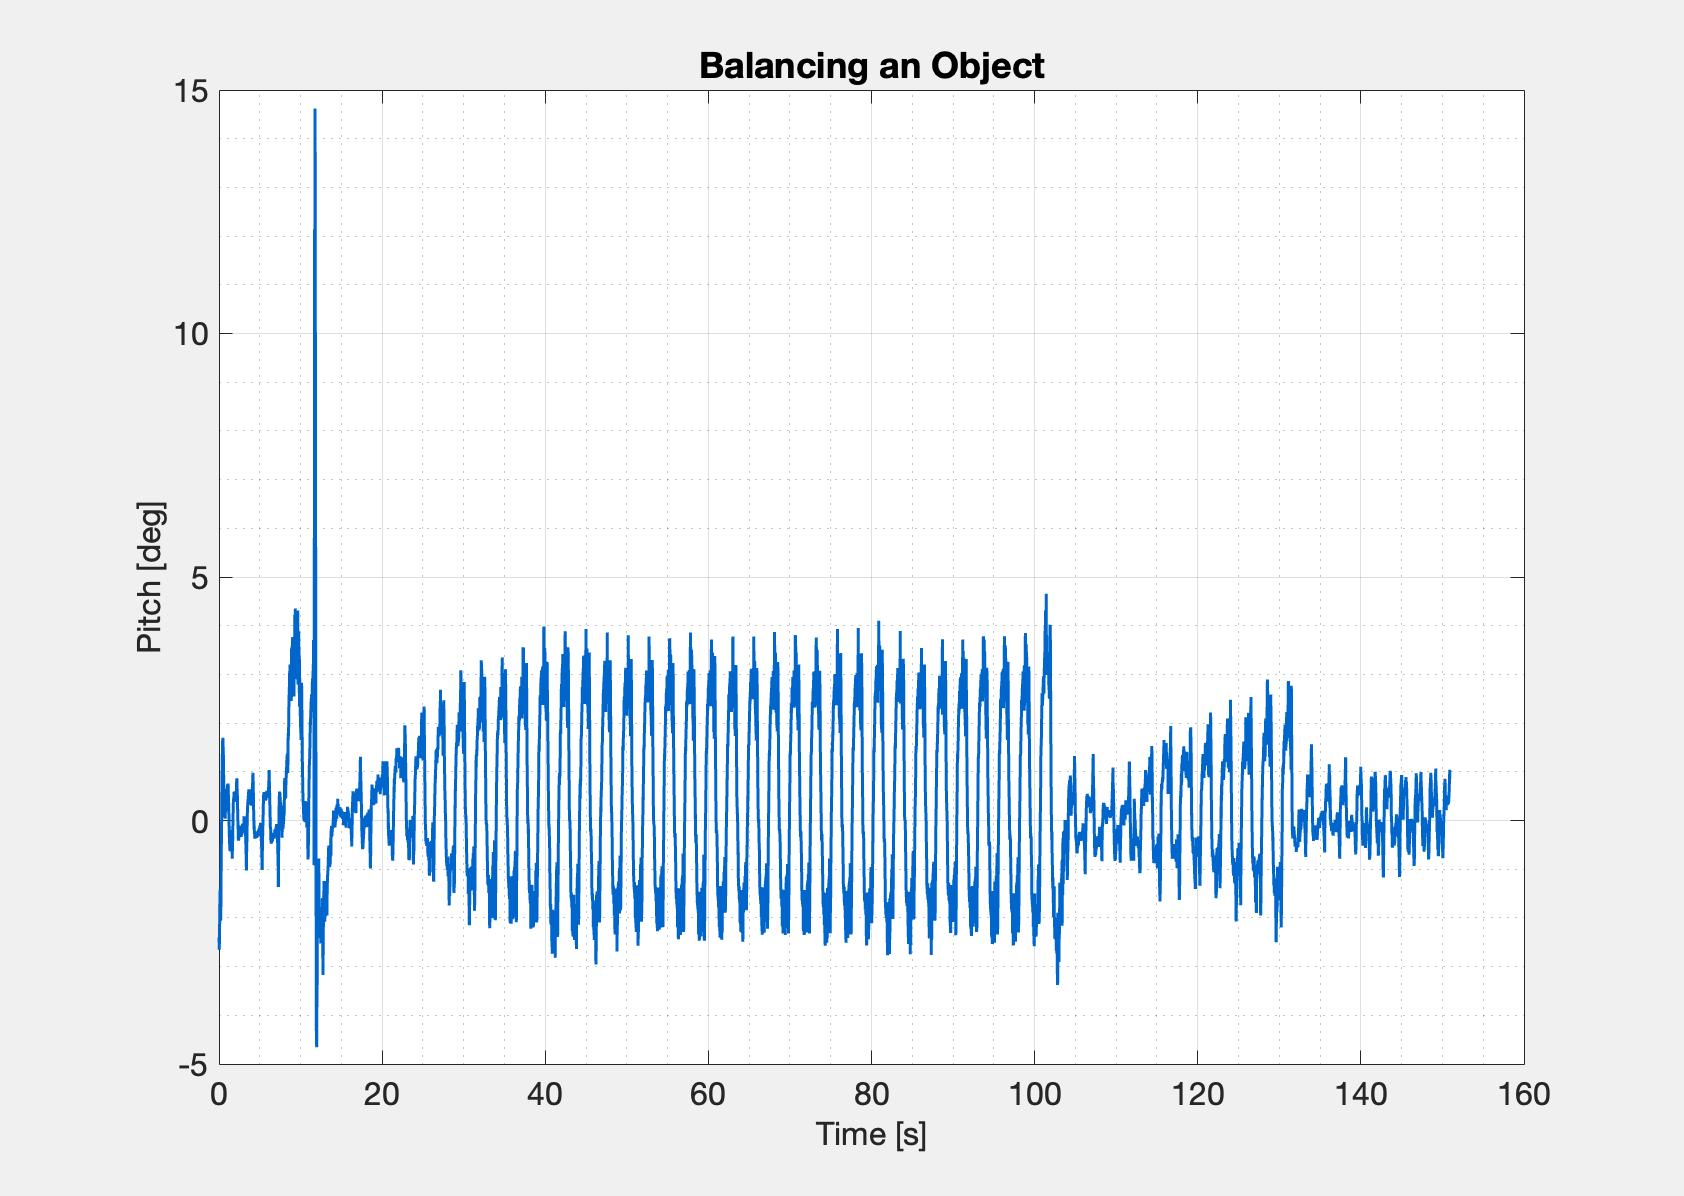

clear; clc; close all;
addpath("utils/")
dataPath = 'DataSets/comshift/com3.csv';
[~, timedelta, data] = parseDataSet(dataPath);

start = 500;
sample_interval = 0.01;
pitch = data(start:end, 1);
num_samples = length(pitch);
time = (0:num_samples-1) * sample_interval; 

fig = figure;
plot(time, pitch, 'Color', [0, 0.4, 0.8], 'LineWidth', 1.5); hold on;

grid on; grid minor;
xlabel('Time [s]');
ylabel('Pitch [deg]');
fontsize(16, "points")
plottitle = 'Balancing an Object';
title(plottitle, 'FontSize', 18);

folderpath = fullfile("..", "Docs", "Y3Report", "Images", "Graphs", filesep);
filepath = fullfile(folderpath, plottitle + ".pdf");
set(fig, 'Units', 'inches', 'Position', [0 0 11.7 8.3]);
exportgraphics(fig, filepath);
set(gcf,'Visible', 'on');